# HW1_1_2

## Add Uniform Noise

close all;
clear;
clc;

As previouse homework we use simple sin function for testing. but add a uniform noise to signal but in range [-0.5, 0.5] time(s).

t   = (-0.5: 0.01: 2);
Amp = 5;
Fs  = 1;

Func        = zeros(1, length(t));

Func(round(1/5*length(t))+1: end)       = Amp*sin(t(round(1/5*length(t))+1: end) * Fs* 2*pi);
NoisyFunc                               = Func;
NoisyFunc(1: round(2/5*length(t))-1)    = Func(1: round(2/5*length(t))-1) + rand(1, round(2/5*length(t)-1));

Plot the signals as explain before.

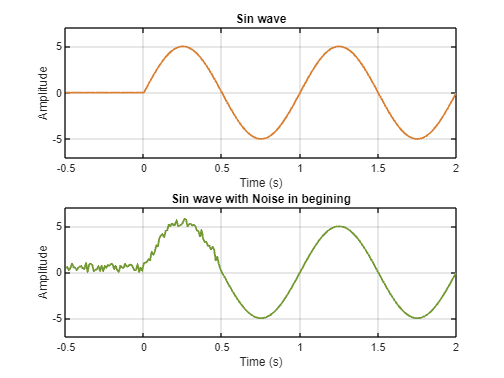

figure('Name', 'Plot Sin wave with Noise in begining')
subplot(2, 1, 1)
plot(t, Func, 'LineWidth', 1.5, 'Color', [0.85, 0.5, 0.2]);
ylim([-7 7])
xlabel('Time (s)');
ylabel('Amplitude');
title('Sin wave');
grid on;
subplot(2, 1, 2)
plot(t, NoisyFunc, 'LineWidth', 1.5, 'Color', [0.45, 0.6, 0.2]);
ylim([-7 7])
xlabel('Time (s)');
ylabel('Amplitude');
title('Sin wave with Noise in begining');
grid on;

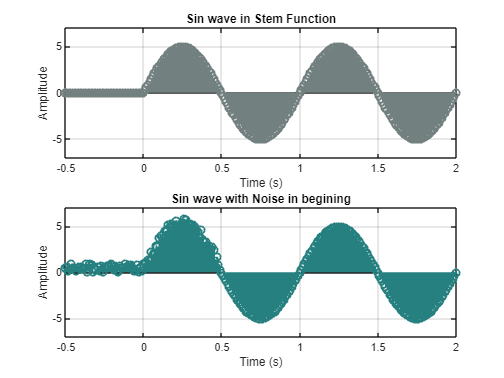

figure('Name', 'Stem Sin wave with Noise in begining')
subplot(2, 1, 1)
stem(t, Func, 'LineWidth', 1.5, 'Color', [0.45, 0.5, 0.5]);
ylim([-7 7])
xlabel('Time (s)');
ylabel('Amplitude');
title('Sin wave in Stem Function');
grid on;
subplot(2, 1, 2)
stem(t, NoisyFunc, 'LineWidth', 1.5, 'Color', [0.15, 0.5, 0.5]);
ylim([-7 7])
xlabel('Time (s)');
ylabel('Amplitude');
title('Sin wave with Noise in begining');
grid on;